# Laboratorio di Automatica (prova del 27 Agosto 2018)

Riccardo Antonello ([riccardo.antonello@unipd.it](mail:riccardo.antonello@unipd.it)) and Angelo Cenedese ([angelo.cenedese@unipd.it](mail:angelo.cenedese@unipd.it)) 

August 27, 2018

Dept. of Information Engineering, University of Padova

## Esercizio 2

In Fig. 2 è riportato uno schema di compensazione del disturbo basato su un *disturbance observer *(DOB) realizzato per mezzo di una configurazione di controllo a 2 gradi di libertà (degrees of freedom - DOF). Nello schema, $P(s)$ è la funzione di trasferimento effettiva dell'impianto, $d$ è il disturbo da stimare, $P_n(s)$ è un modello nominale dell'impianto utilizzato dal DOB, e $Q(s)$ è un opportuno filtro passa-basso utilizzato per la fisica realizzabilità del DOB, e per la reiezione del rumore di misura $n$. 

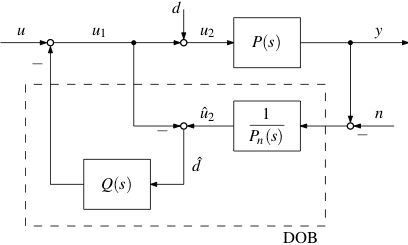

**Figura 2**: disturbance observer (DOB) basato su uno schema di controllo a 2 DOF.

Si assuma che l'impianto sia un motore in corrente continua con funzione di trasferimento:


$$P(s) \,=\, \frac{k_m}{s(T_m s  + 1)}
\qquad\quad\text{con}\qquad\quad
k_m\,=\,5.2\,,\qquad T_m \,=\,0.03$$


Utilizzando esclusivamente le routine del Control System Toolbox, si svolgano i seguenti punti:

1) ricavare le seguenti funzioni di trasferimento:

- $G_{uy}(s) \;=\; Y(s)/U(s)$   :   funzione di trasferimento da ingresso $u$ ad uscita $y$

- $G_{dy}(s) \;=\; Y(s)/D(s)$   :   funzione di trasferimento da disturbo $d$ ad uscita $y$

- $G_{ny}(s) \;=\; Y(s)/N(s)$   :   funzione di trasferimento da rumore di misura $n$ ad uscita $y$

nella condizione "ideale" in cui $P_n(s) \,=\, P(s)$. Per il filtro passa-basso del DOB, si assuma che:


$$Q(s) = \frac{1}{0.005\,s\,+\,1}$$


*Soluzione*.

%   plant tf
km = 5.2; 
Tm = 0.03;
sysP = tf(km, [Tm, 1, 0]);

%   DOB - nominal model tf
sysPn = sysP;

%   DOB - low-pass filter tf
sysQ = tf(1,[0.005, 1]);

%   input u to output y tf (Guy)
sysGuy = zpk( minreal( ...
    sysP*sysPn / (sysQ*(sysP-sysPn) + sysPn ) ...
    ) )


sysGuy =
 
    173.33
  -----------
  s (s+33.33)
 
Continuous-time zero/pole/gain model.




%   disturbance d to output y tf (Gdy)
sysGdy = zpk( minreal( ...
    sysP*sysPn*(1-sysQ) / (sysQ*(sysP-sysPn) + sysPn ) ...
    ) )


sysGdy =
 
       173.33
  -----------------
  (s+200) (s+33.33)
 
Continuous-time zero/pole/gain model.




%   measurement noise n to output y tf (Gny)
sysGny = zpk( minreal( ...
    sysP*sysQ / (sysQ*(sysP-sysPn) + sysPn ) ...
    ) )


sysGny =
 
    200
  -------
  (s+200)
 
Continuous-time zero/pole/gain model.



Se il modello nominale dell'impianto $P_n(s)$ è esatto, ovvero $P_n(s)=P(s)$, allora


$$G_{uy}(s) \,=\, P(s) \quad,\quad
G_{dy}(s) \,=\, P(s)[1-Q(s)]  \quad,\quad
G_{ny}(s) \,=\, Q(s)$$


In particolare:

- il DOB è "trasparente" ad un eventuale anello di controllo esterno, ovvero non influisce sulla dinamica dell'impianto (con compensazione del disturbo) con ingresso $u$ e uscita $y$.

- il filtro passa-basso $Q(s)$ controlla la reiezione del disturbo $n$ sulla uscita y.

2) mostrare, in tre figure distinte, i diagrammi di Bode delle funzioni di trasferimento ottenute al punto 1.

*Soluzione*.

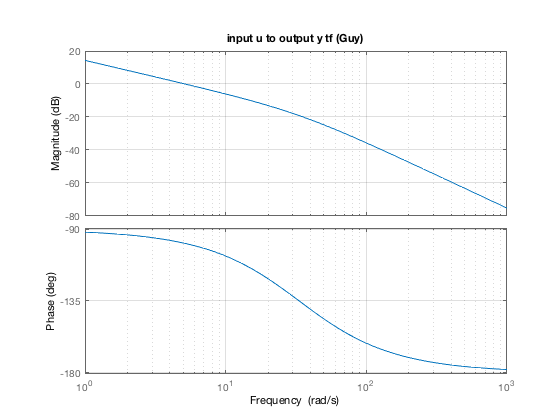

%   input u to output y tf (Guy)
figure(1);
bode(sysGuy);
title('input u to output y tf (Guy)');
grid on;

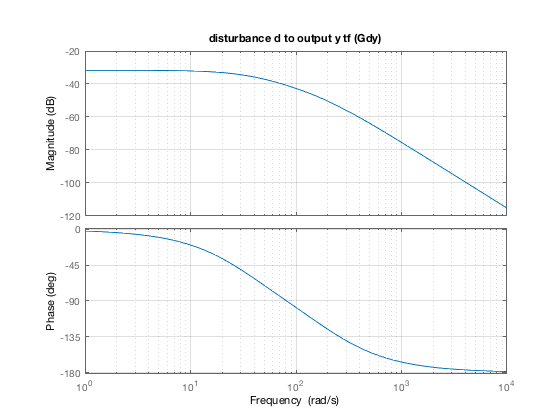


%   disturbance d to output y tf (Gdy)
figure(2);
bode(sysGdy);
title('disturbance d to output y tf (Gdy)');
grid on;

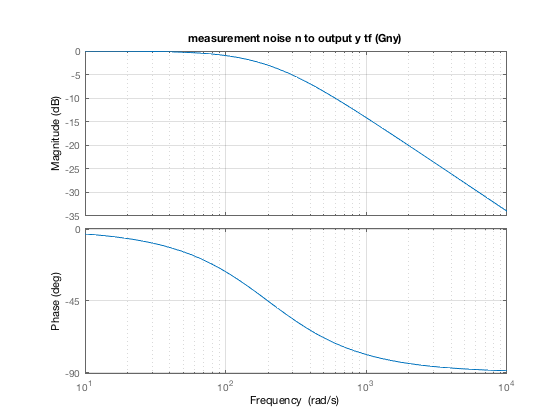


%   measurement noise n to output y tf (Gny)
figure(3);
bode(sysGny);
title('measurement noise n to output y tf (Gny)');
grid on;

3) ripetere il punto 1 assumendo che:


$$P_n(s) \;=\; \frac{ 5 }{ s\,(0.05\,s+1)}$$


che corrisponde alla tipica condizione "reale" in cui il modello dell'impianto utilizzato dal DOB non è perfetto. 

*Soluzione*.

%   DOB - nominal model tf
sysPn = tf(5, [0.05, 1, 0]);

%   input u to output y tf (Guy)
sysGuy = zpk( minreal( ...
    sysP*sysPn / (sysQ*(sysP-sysPn) + sysPn ), ...
    1e-6) )


sysGuy =
 
     173.33 (s+200)
  ---------------------
  s (s+360.8) (s+19.22)
 
Continuous-time zero/pole/gain model.




%   disturbance d to output y tf (Gdy)
sysGdy = zpk( minreal( ...
    sysP*sysPn*(1-sysQ) / (sysQ*(sysP-sysPn) + sysPn ) ...
    ) )


sysGdy =
 
        173.33
  -------------------
  (s+360.8) (s+19.22)
 
Continuous-time zero/pole/gain model.




%   measurement noise n to output y tf (Gny)
sysGny = zpk( minreal( ...
    sysP*sysQ / (sysQ*(sysP-sysPn) + sysPn ), ...
    1e-6) )


sysGny =
 
     346.67 (s+20)
  -------------------
  (s+360.8) (s+19.22)
 
Continuous-time zero/pole/gain model.



4) mostrare i diagrammi di Bode delle funzioni di trasferimento ottenute al punto 3, sovrapponendoli a quelli ottenuti al punto 2.

*Soluzione*.

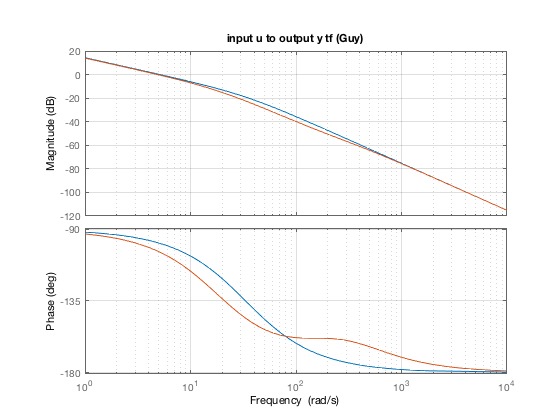

%   input u to output y tf (Guy)
figure(1);
hold on;
bode(sysGuy);

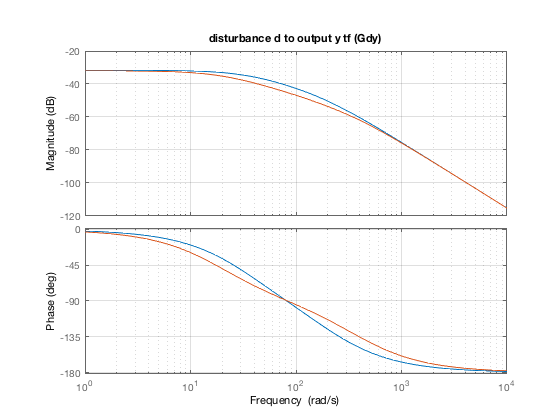


%   disturbance d to output y tf (Gdy)
figure(2);
hold on;
bode(sysGdy);

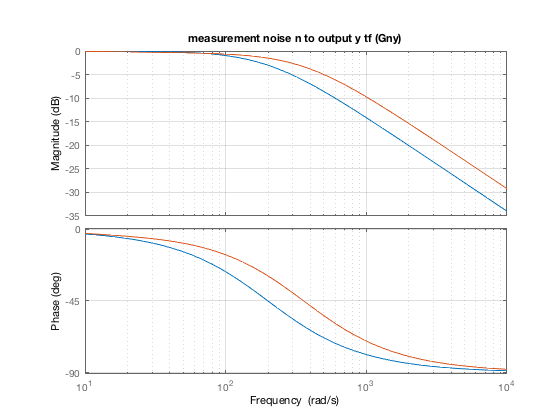


%   measurement noise n to output y tf (Gny)
figure(3);
hold on;
bode(sysGny);